# LEARNING MOTION PATTERNS IN AIS DATA AND DETECTING ANOMALOUS BEHAVIOR

unique(HawaiiAIS2019123120200330.MMSI);

k=find(HawaiiAIS2019123120200330.MMSI==245206000);

Unable to resolve the name 'HawaiiAIS2019123120200330.MMSI'.

dataSubset = HawaiiAIS2019123120200330(k, :);

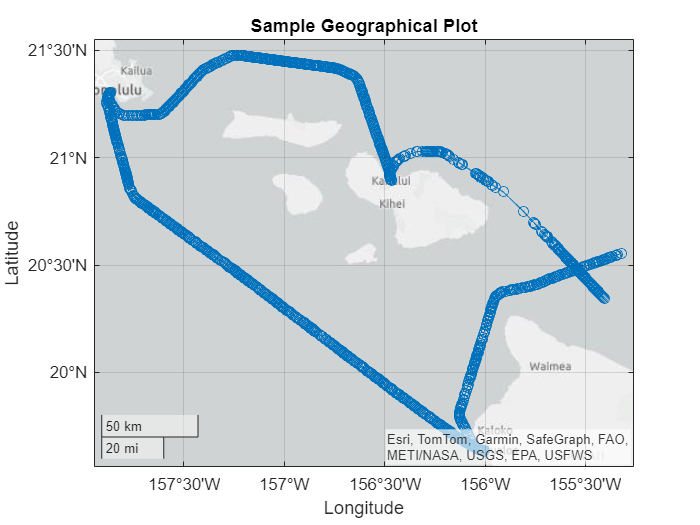

figure
% Create a geographical plot
geoplot(dataSubset.LAT, dataSubset.LON, 'o-')
title('Sample Geographical Plot')

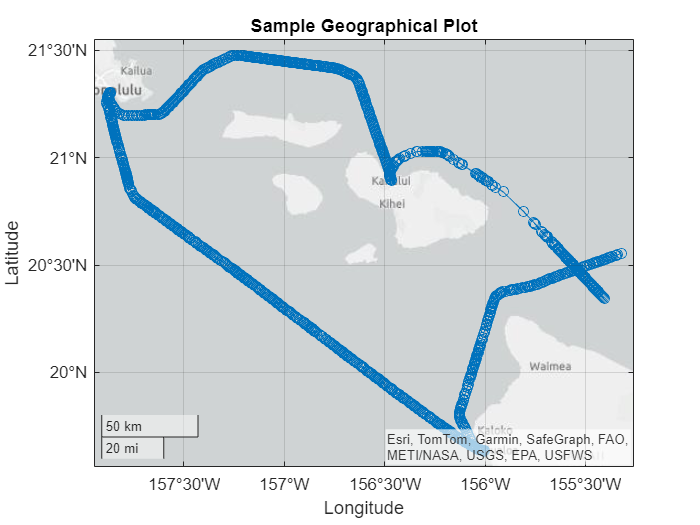

% dataSubset=dataSubset(1:300,:);
[x,y,utmzone]=deg2utm(dataSubset.LAT, dataSubset.LON);
[o_Lat, o_Lon]=utm2deg(x,y,utmzone);
figure
% Create a geographical plot
geoplot(o_Lat, o_Lon, 'o-')
title('Sample Geographical Plot')

% Assuming temp is a table and BaseDateTime is a column in the 'dd/mm/yyyy HH:MM' format
dataSubset.BaseDateTime = datetime(dataSubset.BaseDateTime,'InputFormat','dd/MM/yyyy HH:mm');

% Convert datetime to seconds since epoch (Unix timestamp)
d = posixtime(dataSubset.BaseDateTime);

% Calculate time elapsed since the first timestamp
Tsec = d - d(1);
% Assuming 'Tsec' is your array of timestamps in seconds
diff_Tsec = diff(Tsec);

% Find the most common difference, which will be your sample time Ts
Ts = mode(diff_Tsec);

% state vector x=[LAT LON SOG HEADING]
state_vector=[x,y,dataSubset.SOG, deg2rad(dataSubset.Heading)];
state_vector=state_vector';
g_k_state=ones(2,1);

% Initialize the state history
x_hist = state_vector(:,1);
g_k_hist=g_k_state;
% Simulation loop
for index= 2:1:length(state_vector)
    w=rand(2,1);
    % Define the state transition matrix;
    %cambiare Ts(metterlo costante ricompianare)
    F_xk=[1 0 Ts*cos(state_vector(4,index-1)) 0;...
        0 1 Ts*sin(state_vector(4,index-1)) 0;...
        0 0 1 0;...
        0 0  0 1;];
    G_xk=[cos(state_vector(4,index-1))*Ts^2/2 0;...
          sin(state_vector(4,index-1))*Ts^2/2 0;...
          Ts                                  0;
          0                                  Ts];
    x_dot= F_xk*state_vector(:,index)+G_xk*g_k_state;
    g_dot=eye(2)*g_k_state;

    
    % Store the state history
    x_hist = [x_hist, x_dot];
    g_k_hist=[g_k_hist,g_k_state];

    g_k_state=g_dot;
end

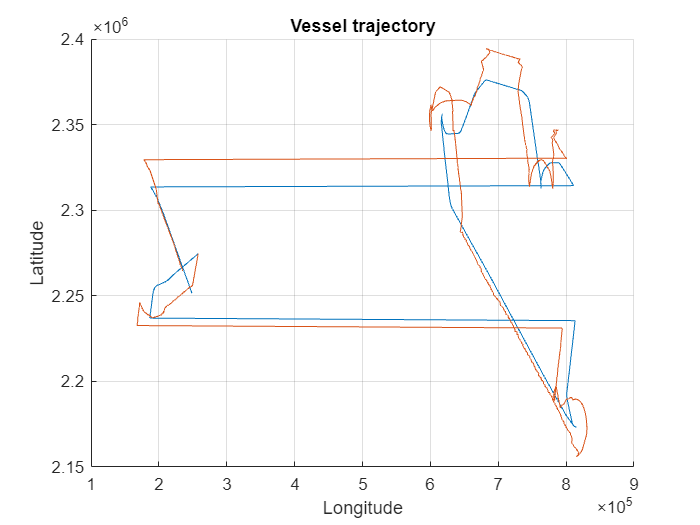


% Plot the latitude and longitude

figure
hold on
plot(x,y)
plot(x_hist(1,:), x_hist(2,:))
xlabel('Longitude')
ylabel('Latitude')
title('Vessel trajectory')
grid on

[m_Lat, m_Lon]=utm2deg(x_hist(1,:),x_hist(2,:),utmzone);


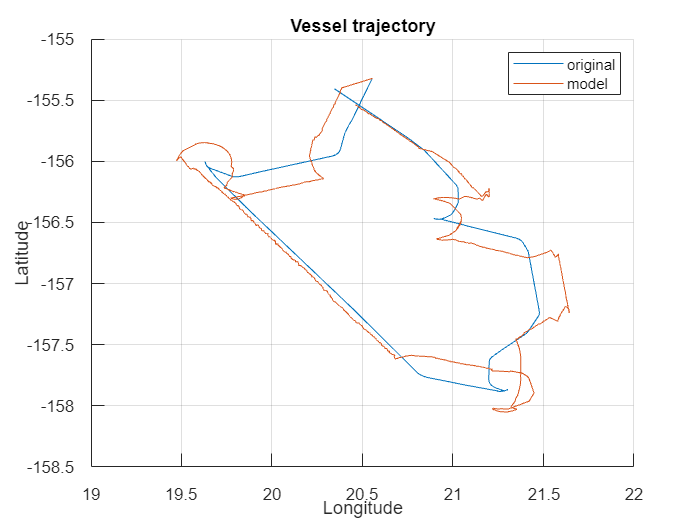


figure
hold on
plot(o_Lat, o_Lon)
plot(m_Lat, m_Lon)
xlabel('Longitude')
ylabel('Latitude')
title('Vessel trajectory')
legend('original','model')
grid on

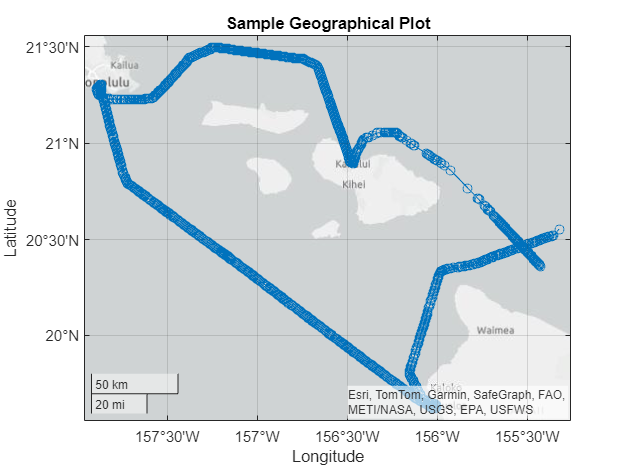

figure
% Create a geographical plot
geoplot(m_Lat, m_Lon, 'o-')
title('Sample Geographical Plot')

%observer kalman filter
state_vector=[x,y,dataSubset.SOG, deg2rad(dataSubset.Heading)];
